1(a)

normdistr = randn(4)

normdistr =     0.5377    0.3188    3.5784    0.7254
    1.8339   -1.3077    2.7694   -0.0631
   -2.2588   -0.4336   -1.3499    0.7147
    0.8622    0.3426    3.0349   -0.2050


%1(b)
positivevector = normdistr(normdistr>0)

positivevector =     0.5377
    1.8339
    0.8622
    0.3188
    0.3426
    3.5784
    2.7694
    3.0349
    0.7254
    0.7147


%1(c)
[row,col] = find(normdistr>0)

row =      1
     2
     4
     1
     4
     1
     2
     4
     1
     3


col =      1
     1
     1
     2
     2
     3
     3
     3
     4
     4


%1(d)
wherepositive = normdistr>0

wherepositive = 4×4 logical array
   1   1   1   1
   1   0   1   0
   0   0   0   1
   1   1   1   0


%2
first = ones(4,4)*normdistr(1,1);
Eucliddist = abs(normdistr - first)

Eucliddist =          0    0.2189    3.0407    0.1877
    1.2962    1.8454    2.2318    0.6007
    2.7965    0.9713    1.8876    0.1771
    0.3245    0.1950    2.4973    0.7426


%3(a)
I = imread('/Users/utkarsh/Downloads/img_001.ppm');
size(I)

ans =    605   700     3


%605 represents the height, 700 represents the width and 3 is for R, G and B values for each pixel
x = min(reshape(I,1,700*605*3))

x = uint8
0

x = max(reshape(I,1,700*605*3))

x = uint8
255

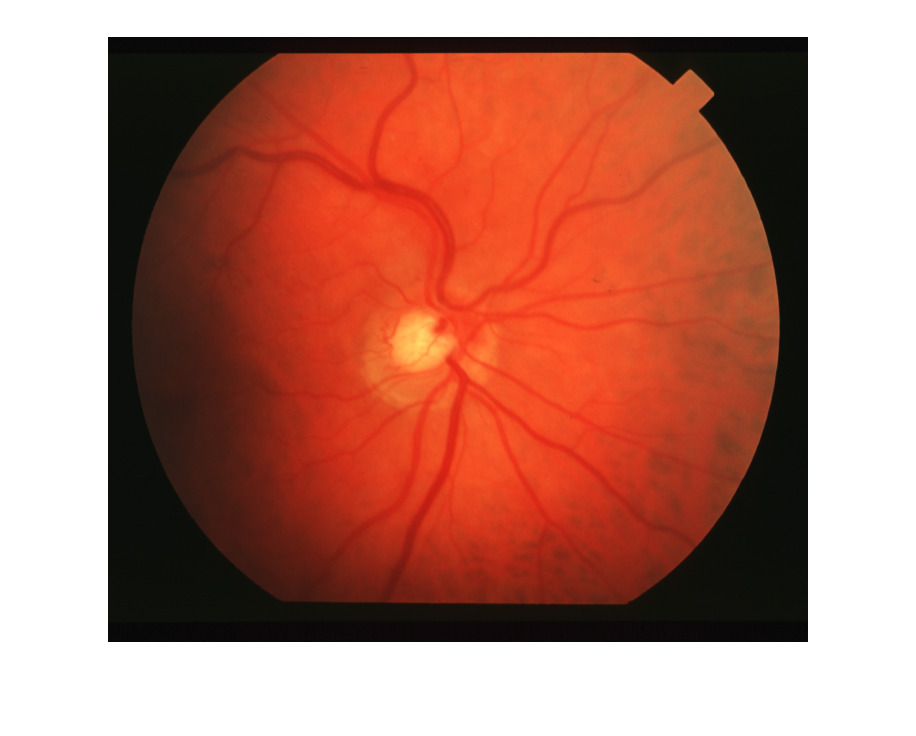

%The range of value of values is 0-255
%3(b)
%*imshow
%->imshow treats the argument as an image and thus has default settings such as maintaining the aspect 
%ratio and turning off the axes but image visualizes your matrix as simply a matrix of numbers. 
%The colors when using image used to represent each value might not have be meaningful to the image.
%->Like image, imagesc also doesn't by default maintain the aspect ratio or
%turn off the axis but it allows you to scale the image.
%->imshow should be used when you want to maintain the aspect ratio and
%not have axes on the image by default.
%*image
%->image displays the data in an array as an image. It does not turn off
%the axes or maintain the aspect ratio like imshow. image is similar to
%imagesc except the data is automatically scaled, so that the image range
%spans the full colormap.
%->Use image when you want to visualize an array as an image but don't need
%automatic scaling.
%*imagesc
%->imagesc is used to visualize an array while automatically scaling the
%image to use the full colormap. It does not turn off the axes or maintain
%the aspect ratio. Unlike image, it automatically scales the image to use
%the full colormap.
%->imagesc should be used to visualize an array like an image while using
%the full colormap.
figure('Name','imshow')
imshow(I)

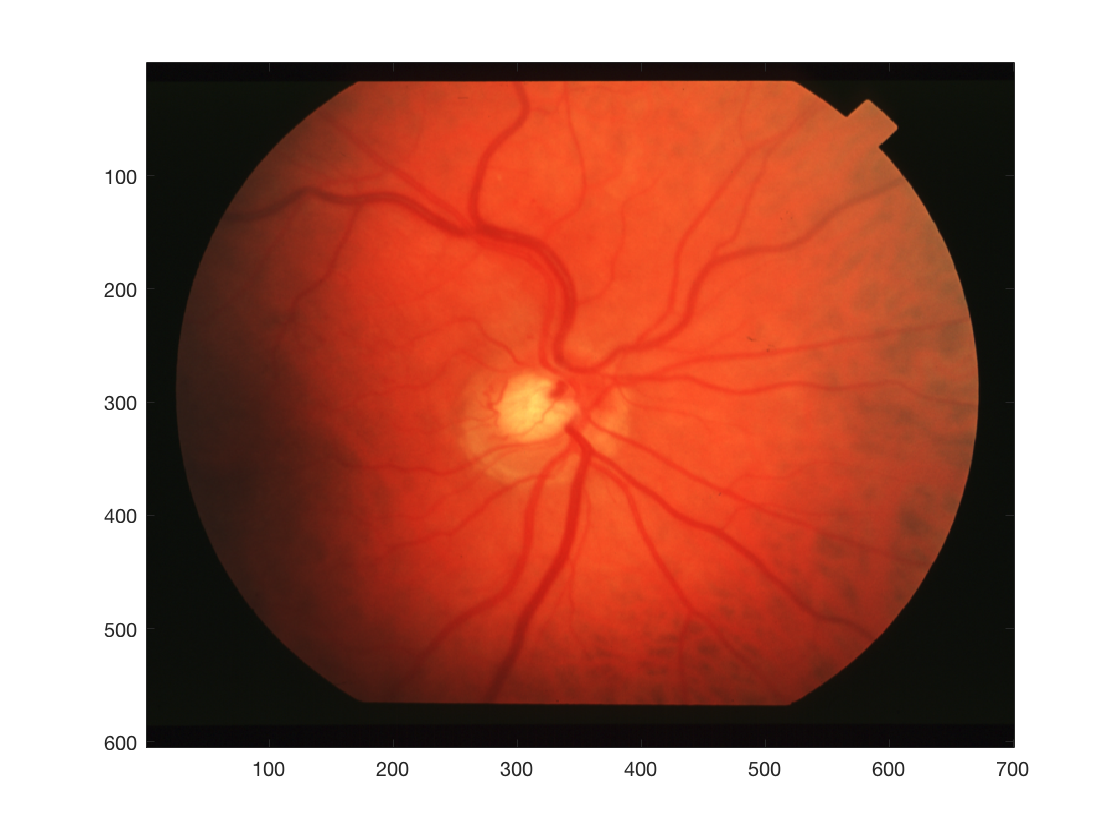

figure('Name','image')
image(I)

figure('Name','imagesc')
imagesc(I)

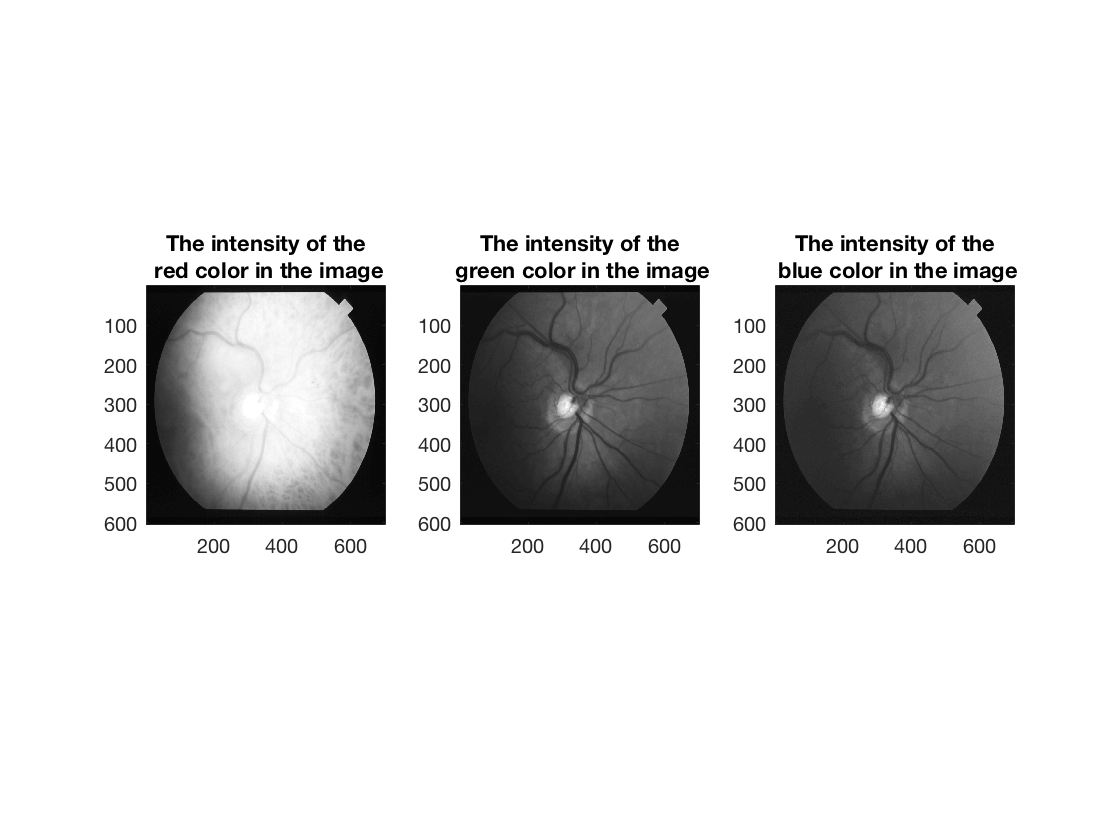

%3(c)
I = imread('/Users/utkarsh/Downloads/img_001.ppm');
one = I(:,:,1);
two = I(:,:,2);
three = I(:,:,3);
figure
subplot(1,3,1)
imagesc(one)
title({'The intensity of the',' red color in the image'})
colormap(gray)
axis('square')
subplot(1,3,2)
imagesc(two)
title({'The intensity of the',' green color in the image'})
colormap(gray)
axis('square')
subplot(1,3,3)
imagesc(three)
title({'The intensity of the',' blue color in the image'})
colormap(gray)
axis('square')

%In this part imagesc isn't taking the weighted average of the R,G and B
%values for each pixel when displaying the image. Since a single 
%color channel is being passed to imagesc, it is only displaying the
%intensity of that color for each pixel.

%4
dblearray = double(one);
img_filt = zeros(605,700);
for x = 2:604
    for y = 2:699
        p = reshape(dblearray(x-1:x+1,y-1:y+1),9,1);
        img_filt(x,y) = mean(p);
    end
end
img_filt(1:5,1:5)

ans =          0         0         0         0         0
         0   10.1111    9.8889   10.5556   10.4444
         0   10.0000    9.7778   10.0000   10.0000
         0   10.2222   10.0000    9.7778    9.5556
         0   10.2222    9.7778    9.2222    9.2222


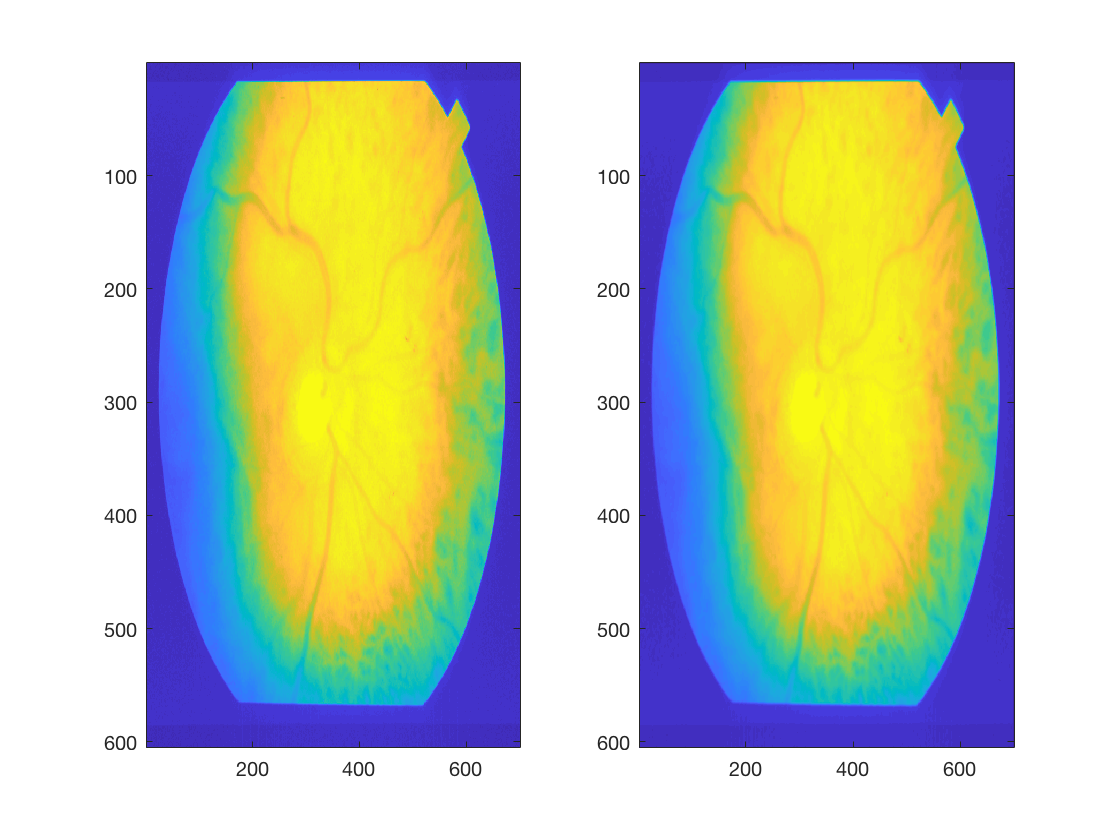

figure
subplot(1,2,1);
imagesc(one);
subplot(1,2,2);
imagesc(img_filt);

%5
%(a)
a = -3:0.1:3;
b = -3:0.1:3;
%(b)
[A,B] = meshgrid(a,b);
size(A)

ans =     61    61


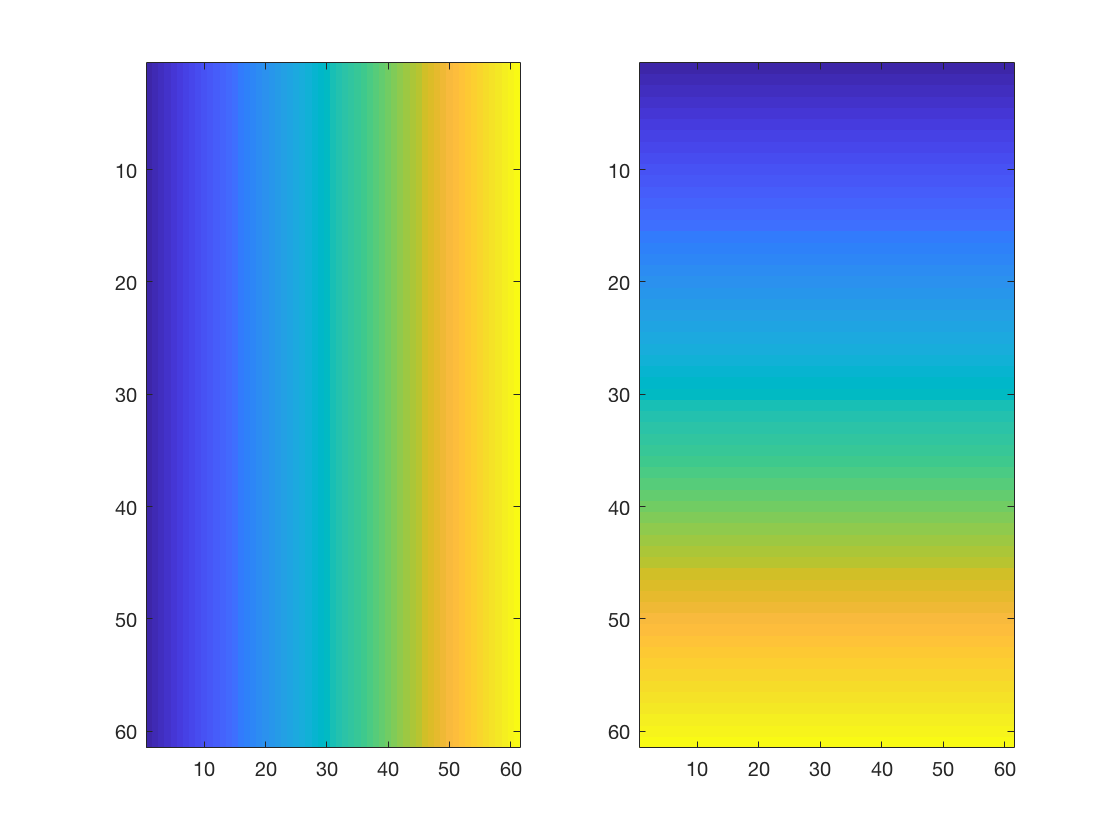

figure
subplot(1,2,1)
imagesc(A)
subplot(1,2,2)
imagesc(B)

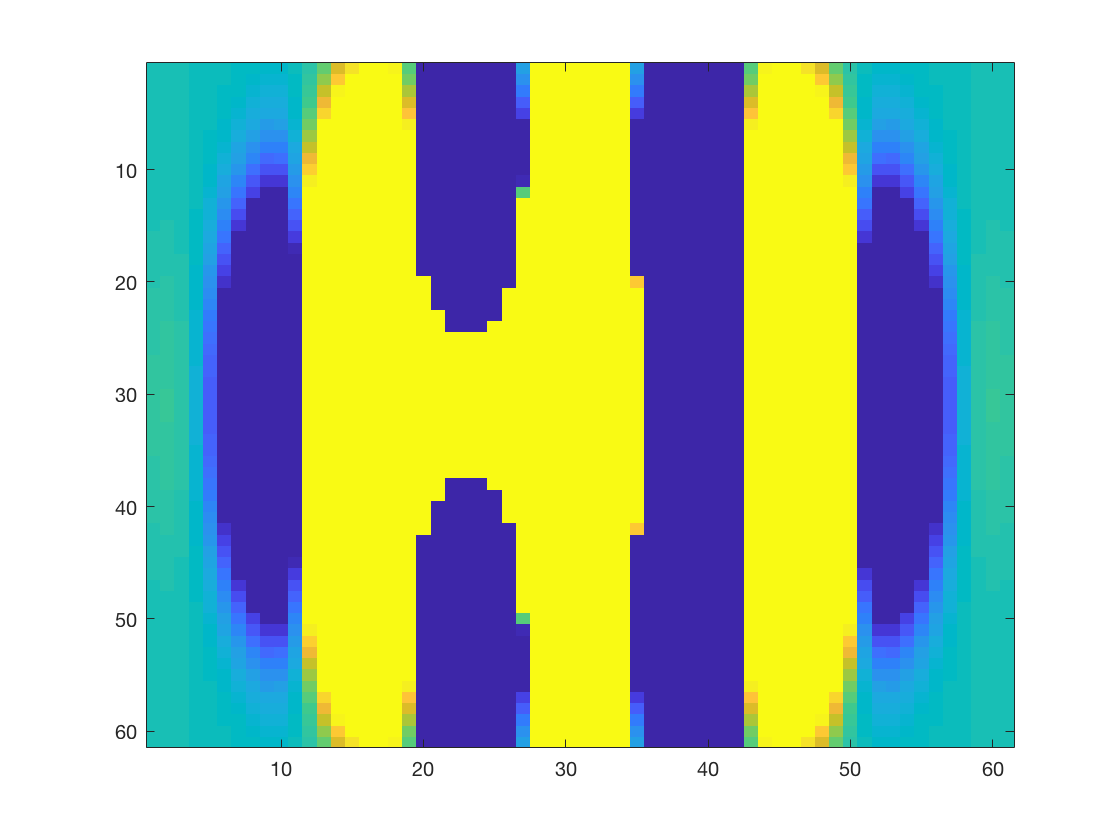

%The arguments to the meshgrid function are the ranges of the x-coordinates
%and the y-coordinates. meshgrid creates 2_D coordinates using the
%arguments passes to it and returns two matrices such that the first matrix
%has the x coordinates and the corresponding element in the second matrix
%has the y coordinate. In the first matrix that is returned, the x value changes
%changes horizontally and in the second matrix that is returned the y
%values change vertically.
%(c)
Z = exp(-(A.^2)-(B.^2)./2).*cos(4*A) + exp(-3*(((A+0.5).^2)+(B.^2)./2));
Z(Z>0.001) = 0.001;
Z(Z<-0.001) = -0.001;
figure
imagesc(Z)

%(d)
% The three dimensions of this image are the a, b and the Z values. The first two dimensions are the the values stored 
% in a and b which give the coordinate of the pixel in the grid and the third dimension is the Z value for the each pixel
%which is a function of it's coordinates. The range for a and b is -3 to 3 and the range
% for Z is -0.001 to 0.001